**Data import, Ropt = 714 Ohm**

clear;
filename = 'Piezo stack impulse test';
sheetname1 = 'Drop test at Ropt';
data = readmatrix(filename,'Sheet',sheetname1);
data = data(2:end,:);

**Power and Voltage output vs. Resistance**

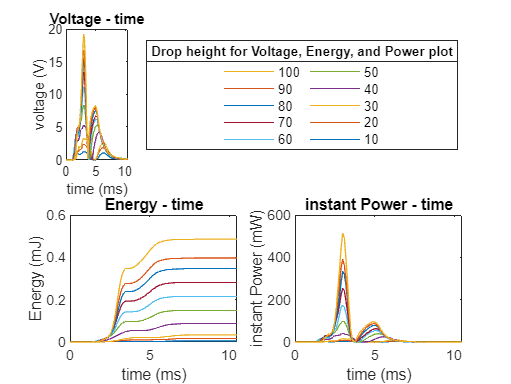

clf
Ropt = 714; %[Ohm]
Height = data(1,1:10:end-9); %[mm]
Power_all = zeros(1,size(data,2)/10);
Energy_output_total = zeros(1,size(data,2)/10);
for i = 1:size(data,2)/10
    [volt,time] = firstImpulse(data(:,10*i-9:10*i));
    subplot(2,2,[1,2]);
    plot(time .*1e3,volt) %plot in ms
    hold on
    [Energy,sum_Energy,Power] = volt2energy(volt,time,Ropt);
    Energy_output_total(i) = sum_Energy; %[J]
    Power_all(i) = Power; %[W]
    subplot(2,2,3);
    plot(time .*1e3,Energy .*1e3) %plot in ms and mJ
    hold on

    instant_Power = volt.^2/Ropt .*1e3;
    subplot(2,2,4);
    plot(time.*1e3,instant_Power) %plot in ms and mW
    hold on
end
hold off

legend_label = cellfun(@num2str, num2cell(Height), 'UniformOutput', false);
subplot(2,2,[1,2]);
title('Voltage - time')
xlabel('time (ms)')
ylabel('voltage (V)')
lgd = legend(legend_label,'NumColumns',2,'Location','eastoutside','FontSize',8,'Direction','reverse');
title(lgd,'Drop height for Voltage, Energy, and Power plot')

subplot(2,2,3);
title('Energy - time')
xlabel('time (ms)')
ylabel('Energy (mJ)')

subplot(2,2,4);
title('instant Power - time')
xlabel('time (ms)')
ylabel('instant Power (mW)')

**Energy input**

e = 0.55;
vb2 = 2*e*sqrt(2*9.81*Height*1e-3)/(1+38.4/500);
Energy_input = 0.5*0.5*vb2.^2; %[J]

**Energy output vs Energy Input**

figure;
clf
% eff = Energy_output_total./Energy_input .*100;
% disp(eff)

%fit curve
load enso
Energy_relation = fit(transpose(Energy_input(:,3:end).*1e3),transpose(Energy_output_total(:,3:end).*1e3),'poly1');
plot(transpose(Energy_input.*1e3),transpose(Energy_output_total.*1e3),'.b')
hold on
plot(Energy_relation,'m')

**Extrapolation**

input_Energy_extrap = 550:50:1000;
output_Energy_extrap = feval(Energy_relation, input_Energy_extrap);
plot(input_Energy_extrap,output_Energy_extrap,'-')
ylim([0 1.2])
hold off

**Graph label**

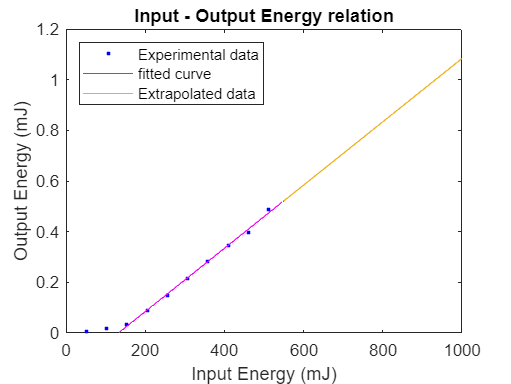

ylabel('Output Energy (mJ)')
xlabel('Input Energy (mJ)')
legend('Experimental data','fitted curve','Extrapolated data','location','northwest')
title('Input - Output Energy relation')

**Input Energy, Average Power, and Peak Voltage**

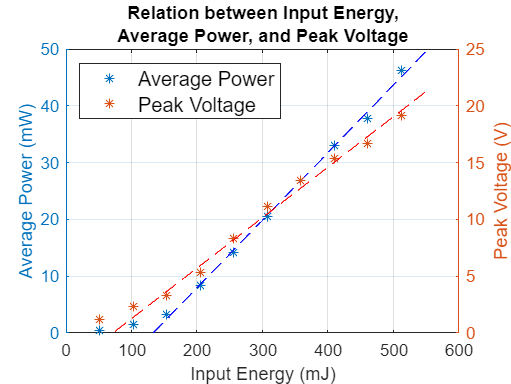

figure;
yyaxis left;
plot(Energy_input*1e3,Power_all*1e3,'*') % [mJ] vs [mW]

%fit curve
load enso
Power_relation = fit(transpose(Energy_input(:,3:end).*1e3),transpose(Power_all(:,3:end)*1e3),'poly1');
hold on
plot(Power_relation,'b')

ylabel('Average Power (mW)')
ylim([0 50])
grid on

yyaxis right;
volt_max = transpose(data(3,1:10:end-9));
plot(Energy_input*1e3,volt_max,'*') % [mJ] vs [V]
volt_relation = fit(transpose(Energy_input(:,3:end).*1e3),volt_max(3:end,:),'poly1');
plot(volt_relation,'r')

ylim([0 25])
ylabel('Peak Voltage (V)')
xlabel('Input Energy (mJ)')
legend('Average Power','','Peak Voltage','location','northwest','Fontsize',12)
title({'Relation between Input Energy,'; 'Average Power, and Peak Voltage'})
hold off

**Power Extrapolation**

**Average power**

figure;
plot(Energy_input*1e3,Power_all*1e3,'*') % [mJ] vs [mW]

%fit curve
load enso
Power_relation = fit(transpose(Energy_input(:,3:end).*1e3),transpose(Power_all(:,3:end)*1e3),'poly1');
hold on
plot(Power_relation,'b')

ylabel('Average Power (mW)')
grid on

**Extrepolated data**

input_Energy_extrap = 550:50:1000;
output_Power_extrap = feval(Power_relation, input_Energy_extrap);
plot(input_Energy_extrap,output_Power_extrap,'-')
plot(800,79.3965,'ro')
xline(800,'r--')
yline(79.3965,'r--')
ylim([0 100])

hold off

**Graph label**

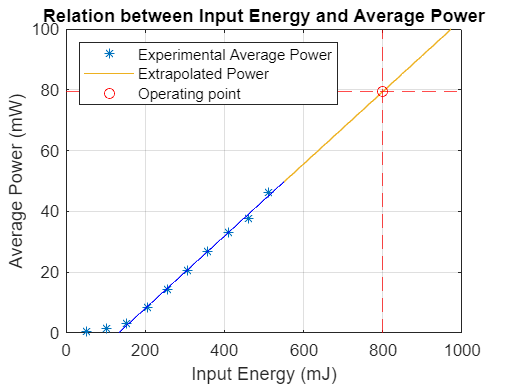

ylabel('Average Power (mW)')
xlabel('Input Energy (mJ)')
legend('Experimental Average Power','','Extrapolated Power','Operating point','location','northwest')
title('Relation between Input Energy and Average Power')

## **This part is for presentation slide**

**Volt-Time plot at Ropt = 714 Ohm, H = 100 mm**

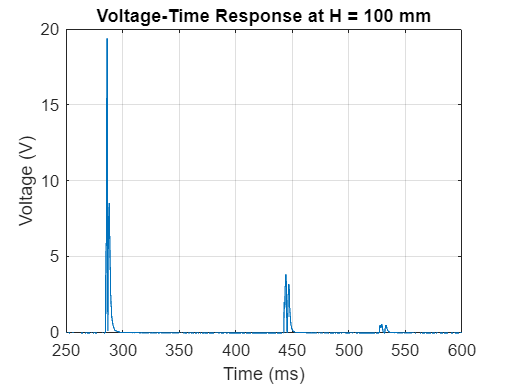

clf

% Voltage-time response of R=885 Ohm and H = 80 mm over the entire time period
% perfect time period = [0.25,0.6]
volt_H100 = data(:,93);
time_H100 = data(:,92);
createGraphWithProperties(time_H100*1e3,volt_H100, ...
    'title','Voltage-Time Response at H = 100 mm', ...
    'xlabel','Time (ms)','ylabel','Voltage (V)','xlim',[250,600])

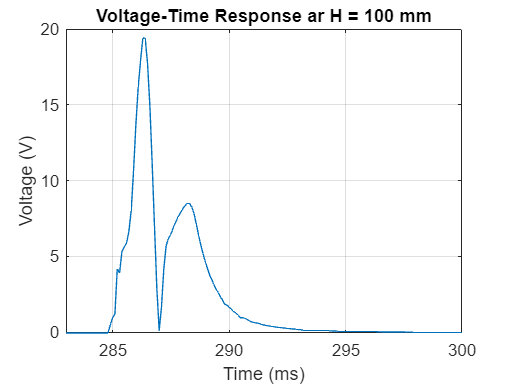


% Zoom in the first peak
createGraphWithProperties(time_H100*1e3,volt_H100, ...
    'title','Voltage-Time Response ar H = 100 mm', ...
    'xlabel','Time (ms)','ylabel','Voltage (V)','xlim',[283,300])

**Energy-Time plot at Ropt = 714 Ohm, H = 100 mm**

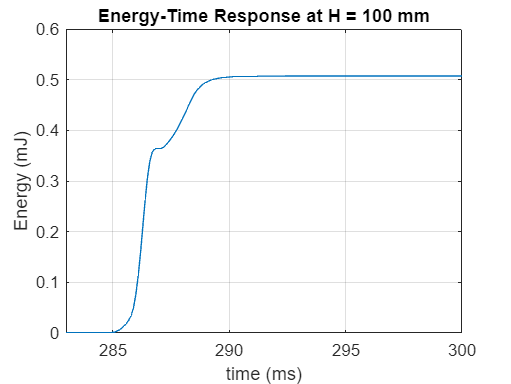

[energy_R885, sum_energy_R885, power_R885] = volt2energy(data(:,93),data(:,92),714);

% Energy-Time response of R=885 Ohm and H = 80 mm over the time period
createGraphWithProperties(time_H100*1e3,energy_R885 *1e3, ...
    'title','Energy-Time Response at H = 100 mm', ...
    'xlabel','time (ms)','ylabel','Energy (mJ)','xlim',[283,300])

**Voltage-Time plot at Ropt = 714 Ohm, H = 30mm, 60mm, 100mm**

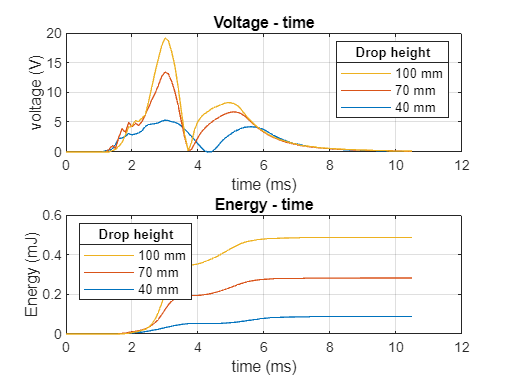

clf
Ropt = 714; %[Ohm]
Power_all = zeros(1,size(data,2)/10);
Energy_output_total = zeros(1,size(data,2)/10);
for i = 1:size(data,2)/10
    if ismember(i,[4,7,10])
        [volt,time] = firstImpulse(data(:,10*i-9:10*i));
        subplot(2,1,1);
        plot(time .*1e3,volt) %plot in ms
        hold on
        [Energy,sum_Energy,Power] = volt2energy(volt,time,Ropt);
        Energy_output_total(i) = max(Energy); %[J]
        Power_all(i) = Power; %[W]
        subplot(2,1,2);
        plot(time .*1e3,Energy .*1e3) %plot in ms and mJ
        hold on
    end
end
hold off

legend_label = {'40 mm','70 mm','100 mm'};
subplot(2,1,1);
title('Voltage - time')
xlabel('time (ms)')
ylabel('voltage (V)')
lgd = legend(legend_label,'NumColumns',1,'Location','northeast','FontSize',8,'Direction','reverse');
title(lgd,'Drop height')
grid on

subplot(2,1,2);
title('Energy - time')
xlabel('time (ms)')
ylabel('Energy (mJ)')
lgd = legend(legend_label,'NumColumns',1,'Location','northwest','FontSize',8,'Direction','reverse');
title(lgd,'Drop height')
grid on